# Q-tree Segmentation / IFS

clc
clearvars
close all

data_dir1 = "./data/audio/control_embd3";
data_dir2 = "./data/audio/dementia_embd3";

dir_info1 = dir(data_dir1);
dir_info2 = dir(data_dir2);

fnames1 = {dir_info1.name};
fnames1 = fnames1(~ismember(fnames1,{'.','..'}));
fnames2 = {dir_info2.name};
fnames2 = fnames2(~ismember(fnames2,{'.','..'}));

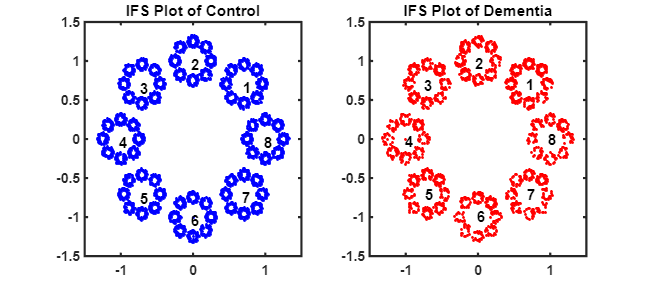

n1 = length(fnames1);
n2 = length(fnames2);

num_id = 8;
alpha = 0.25;

y = table2array(readtable(fullfile(data_dir1,fnames1(randi([1,n1])))));
ot = OcTree(y,'binCapacity',n1/3,'maxDepth',2,'style','weighted');
int_sig = OcTree_state(ot,y,n1);
ifs_coord = IFS(int_sig,num_id,alpha);
ifs_coord(1,:) = [];

figure('Color','w','Position',[0,0,900,400])
subplot(1,2,1)
plot(ifs_coord(:,1),ifs_coord(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(int_sig == i);
    c = mean(ifs_coord(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')    
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Control')
set(gca,'LineWidth',1.5,'FontWeight','bold')
y = table2array(readtable(fullfile(data_dir2,fnames2(randi([1,n2])))));
ot = OcTree(y,'binCapacity',n2/3,'maxDepth',2,'style','weighted');
int_sig = OcTree_state(ot,y,n2);
ifs_coord = IFS(int_sig,num_id,alpha);
ifs_coord(1,:) = [];

subplot(1,2,2)
plot(ifs_coord(:,1),ifs_coord(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(int_sig == i);
    c = mean(ifs_coord(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')    
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Dementia')
set(gca,'LineWidth',1.5,'FontWeight','bold')

# HRQ

feat_mx = NaN(n1+n2,num_id*3+num_id^2*3);
for i=1:n1
    fpath = fullfile(data_dir1, fnames1(i));
    y = table2array(readtable(fpath));
    
    ot = OcTree(y,'binCapacity',n1/3,'maxDepth',2,'style','weighted');
    int_sig = OcTree_state(ot,y,n1);
    
    ifs_coord = IFS(int_sig,num_id,alpha);
    feat_vec1 = heterorecurrence(ifs_coord,int_sig,num_id);
    feat_vec2 = heterorecurrence2(ifs_coord,int_sig,num_id);
    feat_mx(i,:) = [feat_vec1,feat_vec2];
end

for i=1:n2
    fpath = fullfile(data_dir2, fnames2(i));
    y = table2array(readtable(fpath));
    
    ot = OcTree(y,'binCapacity',n2/3,'maxDepth',2,'style','weighted');
    int_sig = OcTree_state(ot,y,n2);
    
    ifs_coord = IFS(int_sig,num_id,alpha);
    feat_vec1 = heterorecurrence(ifs_coord,int_sig,num_id);
    feat_vec2 = heterorecurrence2(ifs_coord,int_sig,num_id);
    feat_mx(n1+i,:) = [feat_vec1,feat_vec2];
end

# PCA / KS Test

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];

w = 1./(var(feat_mx)+eps);
[~,score,~,~,explained] = pca(feat_mx,'VariableWeights',w);

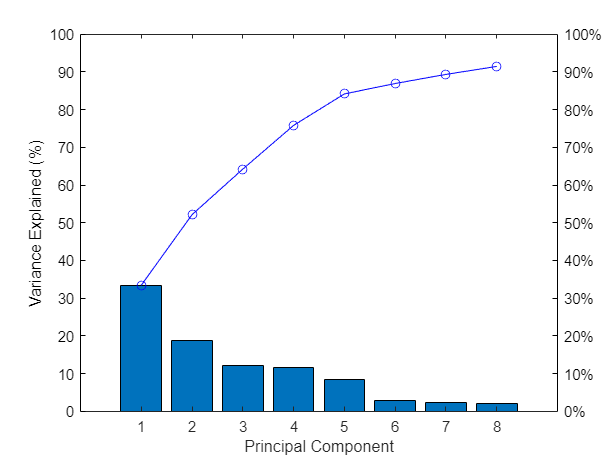

figure
yyaxis left
bar(explained(1:num_id))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:num_id,cumsum(explained(1:num_id)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

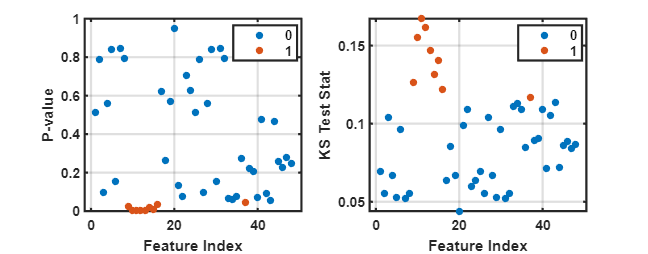

out_mx = NaN(size(feat_mx,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx(1:n1,i),feat_mx(n1+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

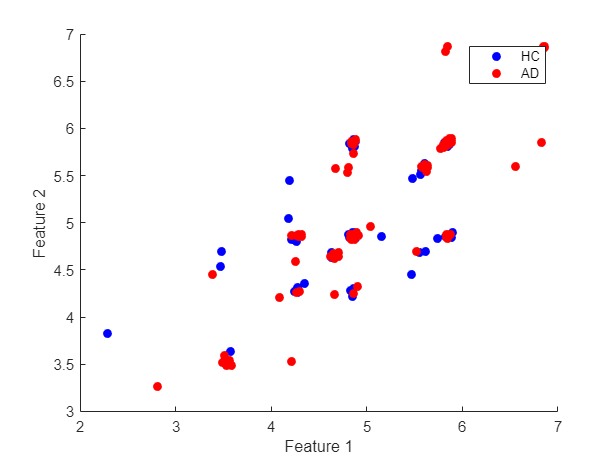

[~,max_idx] = maxk(out_mx(:,3),5);
i1 = max_idx(1);
i2 = max_idx(3);

figure('Color','w')
scatter(feat_mx(1:n1,i1),feat_mx(1:n1,i2),'filled','MarkerFaceColor','b')
hold on
scatter(feat_mx((n1+1):end,i1),feat_mx((n1+1):end,i2),'filled','MarkerFaceColor','r')
hold off
xlabel("Feature 1")
ylabel("Feature 2")
legend(["HC","AD"])

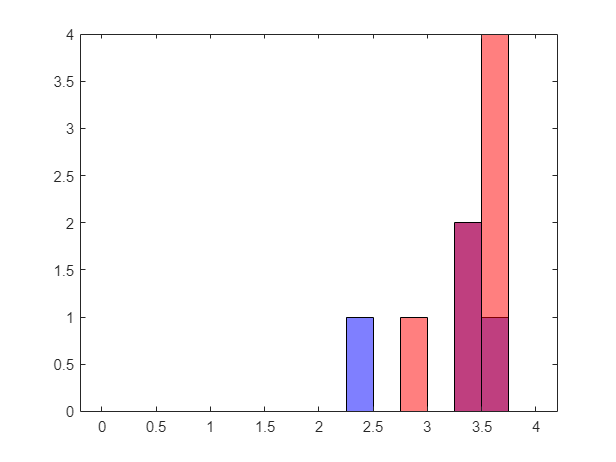

histogram(feat_mx(1:n1,i1),0:0.25:4,'FaceColor','b','FaceAlpha',0.5)
hold on
histogram(feat_mx(n1+1:end,i1),0:0.25:4,'FaceColor','r','FaceAlpha',0.5)
hold off

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.42534 |     0.33783 |     0.42534 |     0.42534 |    0.0014939 |
|    2 | Best   |     0.42308 |     0.85683 |     0.42308 |     0.42421 |   7.2974e-06 |
|    3 | Accept |     0.45928 |    0.088736 |     0.42308 |     0.42806 |      0.13017 |
|    4 | Best   |     0.41855 |     0.87575 |     0.41855 |     0.43141 |   6.5043e-08 |
|    5 | Best   |     0.41629 |     0.81928 |     0.41629 |     0.41629 |   2.0598e-07 |
|    6 | Accept |     0.42081 |     0.52468 |     0.41629 |      0.4163 |   0.00014207 |
|    7 | Accept |     0.42081 |     0.81261 |     0.41629 |      0.4183 |   4.7395e-07 |
|    8 | Accept |    

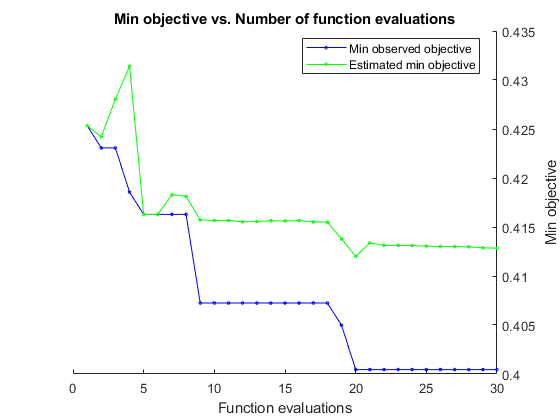

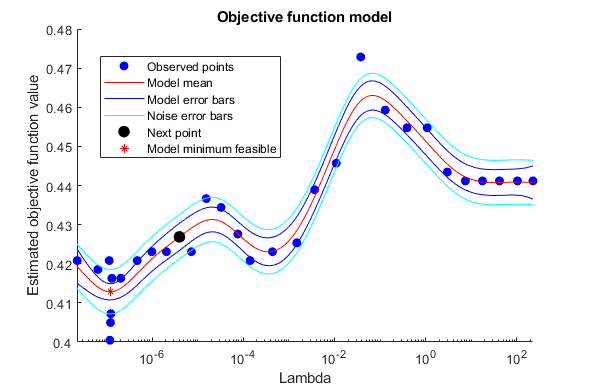


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 26.1573 seconds
Total objective function evaluation time: 14.5303

Best observed feasible point:
      Lambda  
    __________

    1.1903e-07

Observed objective function value = 0.40045
Estimated objective function value = 0.41284
Function evaluation time = 0.80087

Best estimated feasible point (according to models):
      Lambda  
    __________

    1.2275e-07

Estimated objective function value = 0.41284
Estimated function evaluation time = 0.83738



% feat_mx2 = feat_mx(:,out_mx(:,3) > quantile(out_mx(:,3),0.9));
feat_mx2 = feat_mx;
ybool = zeros(size(feat_mx2,1),1);
ybool(n1+1:end) = 1;
ybool = logical(ybool);

test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(feat_mx2(trn_idx,:)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

yhat = predict(mdl,feat_mx2(eval_idx,:));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    17    31
    15    47



statsOfMeasure(c,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"          17         47         32          32 
    "false_positive"         15         31         23          23 
    "false_negative"         31         15         23          23 
    "true_negative"          47         17         32          32 
    "precision"         0.53125    0.60256    0.56691     0.58182 
    "sensitivity"       0.35417    0.75806    0.55612     0.58182 
    "specificity"       0.75806    0.35417    0.55612     0.58182 
    "accuracy"          0.58182    0.58182    0.58182     0.58182 
    "F-measure"           0.425    0.67143    0.54821     0.58182 
